h = logspace(-20,0,100);

x0 = pi/4;
derivative= dydx(x0);

dydx_approx = (sin(x0+h)-sin(x0))./ h           %IMPLEMENT equation (2.2) here 

dydx_approx =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.6107    1.0116    1.2706    0.7980    0.7517    0.7869    0.6918    0.7448    0.7407    0.7345    0.7073    0.7146    0.7095    0.7084    0.7080    0.7075    0.7076    0.7074    0.7070    0.7071    0.7073    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071    0.7071


abserr = abs(derivative - dydx_approx);
truncation_error = sin(x0) .* h / 2                                

truncation_error =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


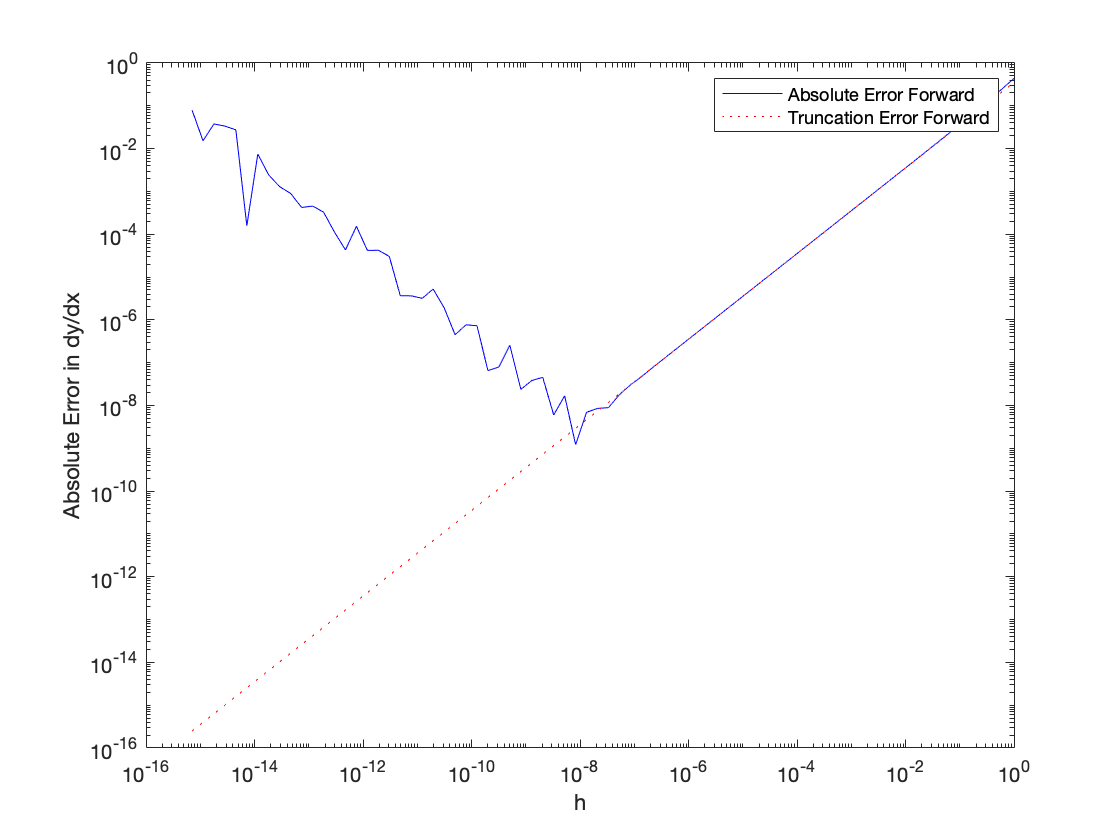


clf
figure(1)
loglog(h(25:100),abserr(25:100),'b')
hold on
figure(1)
loglog(h(25:100),truncation_error(25:100),'r:')

xlabel('h')
ylabel('Absolute Error in dy/dx')

legend('Absolute Error Forward','Truncation Error Forward')

function der = dydx(x0)
    der = cos(x0);
end

